# Resonators In Real-time Processing

This live script implements the system of four parallel resonant bandpass filters shown in Fig. 8.15 of 

### "Discrete-Time Signals and Systems: A MATLAB Integrated Approach"

The input to the system is a guitar note "A3" contained in the file "GuitarA3.flac".  The aim of the system is to pick the fundamental frequency $f_{0}=110$ Hz and the three odd harmonics (330, 550 and 770 Hz) and add them together.  The processing is done on a frame-by-frame basis, and the resulting audio is played back with each frame.  The system function for each resonant bandpass filter is in the form


$$H_{i}\left(z\right)=\frac{K_{i}\,\left(z^{2}-1\right)}{z^{2}-2r\,\cos\left(\Omega_{0i}\right)\,z+r^{2}}$$


For details see Section 8.3.1 of the text, and also MATLAB Exercise 8.3.

#### Create objects for *audio file reader* and *audio player*

clear all
sReader = dsp.AudioFileReader('GuitarA3.flac');
sPlayer = audioDeviceWriter('SampleRate',sReader.SampleRate);
fs = sReader.SampleRate;  % Sampling rate from the audio file

Omgb = 2*pi*60/fs;       % Bandwidth for all four filters to be designed
Omega = [-1:0.001:1]*pi;
freq = Omega/(2*pi)*fs;  % Convert to actual frequencies

#### Bandpass filter 1

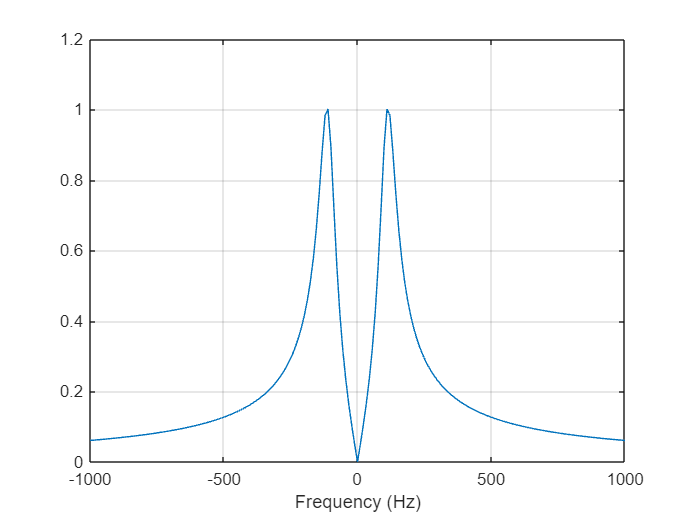

Omg01 = 2*pi*110/fs;                           % Center frequency for filter 1
[r1,gain1,zrs1,pls1] = ss_respar(Omg01,Omgb);  % Parameters for filter 1
mag1 = ss_freqz(zrs1,pls1,gain1,Omega);
plot(freq,mag1); grid;
axis([-1000,1000,0,1.2]);
xlabel('Frequency (Hz)');

#### Bandpass filter 2

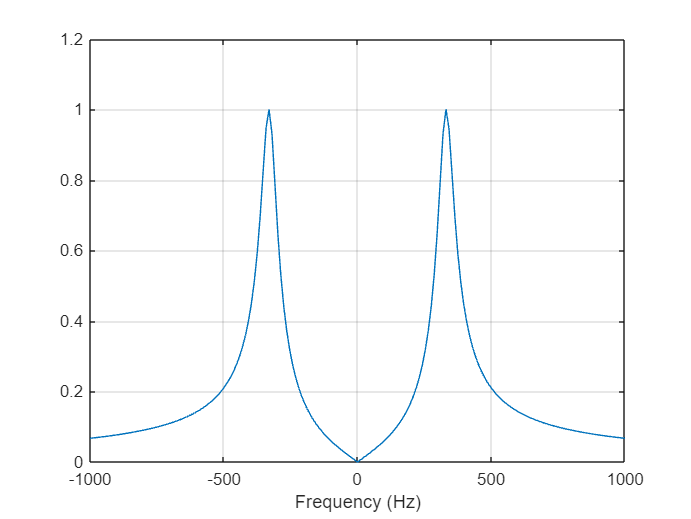

Omg02 = 2*pi*330/fs;                           % Center frequency for filter 2
[r2,gain2,zrs2,pls2] = ss_respar(Omg02,Omgb);  % Parameters for filter 2
mag2 = ss_freqz(zrs2,pls2,gain2,Omega);
plot(freq,mag2); grid;
axis([-1000,1000,0,1.2]);
xlabel('Frequency (Hz)');

#### Bandpass filter 3

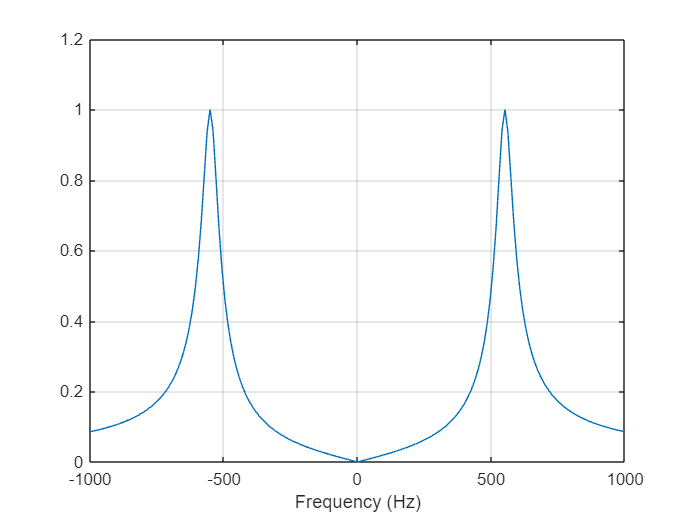

Omg03 = 2*pi*550/fs;                           % Center frequency for filter 3
[r3,gain3,zrs3,pls3] = ss_respar(Omg03,Omgb);  % Parameters for filter 3
mag3 = ss_freqz(zrs3,pls3,gain3,Omega);
plot(freq,mag3); grid;
axis([-1000,1000,0,1.2]);
xlabel('Frequency (Hz)');

#### Bandpass filter 4

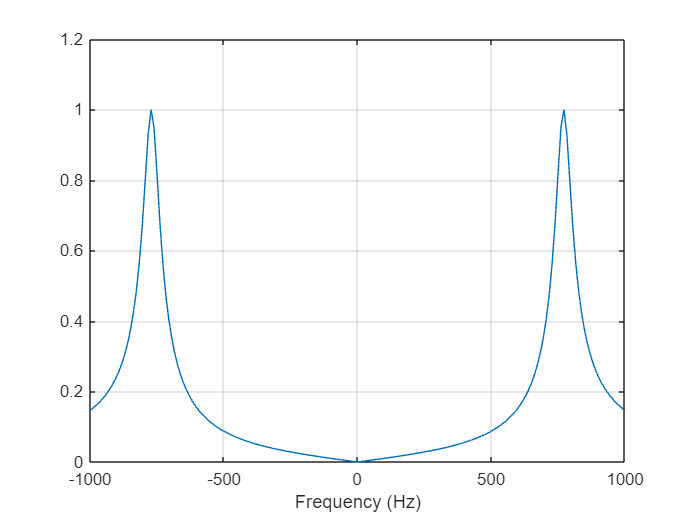

Omg04 = 2*pi*770/fs;                           % Center frequency for filter 4
[r4,gain4,zrs4,pls4] = ss_respar(Omg04,Omgb);  % Parameters for filter 4
mag4 = ss_freqz(zrs4,pls4,gain4,Omega);
plot(freq,mag4); grid;
axis([-1000,1000,0,1.2]);
xlabel('Frequency (Hz)');

#### Frame-by-frame processing loop

nChannels = info(sReader).NumChannels;  % Number of channels
buffer1 = zeros(2,nChannels);           % Buffer for filter 1 
buffer2 = zeros(2,nChannels);           % Buffer for filter 2
buffer3 = zeros(2,nChannels);           % Buffer for filter 3
buffer4 = zeros(2,nChannels);           % Buffer for filter 4
while ~isDone(sReader)                   
  x = sReader();                                
  [w1,buffer1] = ss_resf(x,Omg01,r1,gain1,buffer1);
  [w2,buffer2] = ss_resf(x,Omg02,r2,gain2,buffer2);
  [w3,buffer3] = ss_resf(x,Omg03,r3,gain3,buffer3);
  [w4,buffer4] = ss_resf(x,Omg04,r4,gain4,buffer4);
  y = w1+w2+w3+w4;                      % Compute output frame
  sPlayer(y);
end
release(sReader);  % We are finished with the input audio file
release(sPlayer);  % We are finished with the audio output device